clc,clear,close all
c = 3e8;                         %光速 
Tr = 1024e-7;                    %脉冲重复周期
totalR=c*Tr/2

totalR = 15360

f0 = 1e10;                      %载频
Tp = 5e-6;                      %脉冲宽度
B =10e6;                         %带宽
u = B/Tp;                        %调频率
fs = 4*B;  %32*B;                      %采样率
N = 64; %128       
t = 1/fs:1/fs:Tr;               %回波信号时间序列
SampleNumber=fix(fs*Tr)         %一个脉冲周期的采样点数；

SampleNumber = 4096

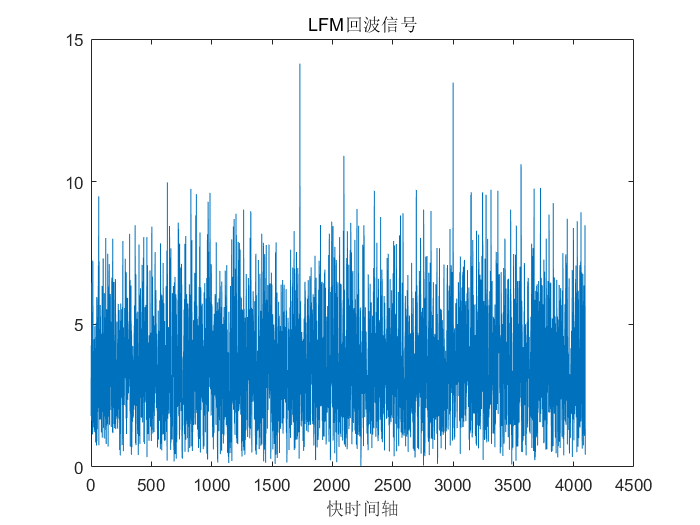

targetNumber=4;                            %目标个数
R0 = [3e3,3.1e3,5e3,13e3];                  %目标距离
v = [20,70,50,30];                           %径向速度
pnum = 4;                                  %保护单元
rnum = 10;                                 %参考单元
pfa = 1e-6;                                %恒虚警率
M_scale=32;                                %MTD的多普勒门
noisepwr=4;
%%================= 回波信号产生===================%%
tt=0:1/fs:Tr-1/fs;
signal=zeros(N,SampleNumber);
for k=1:targetNumber
    for kk=1:N
        R=R0(k)-v(k)*(kk-1)*Tr;
        t=tt-2*(R-v(k)*tt)/c;
%         windowStart=ceil(2*R*fs/c);
%         windowWidth=fix(Tp*fs);
%         window=[zeros(1,windowStart-1),ones(1,windowWidth),zeros(1,SampleNumber-windowStart-windowWidth+1)];
        signal(kk,:)=signal(kk,:)+(t>=0&t<Tp).*exp(j*pi*u*t.^2).*exp(-j*2*pi*f0*t);
    end
end
for kkk=1:N
    noise=noisepwr*(1/sqrt(2))*(randn(1,length(t))+j*randn(1,length(t)));
    signal(kkk,:)=signal(kkk,:)+noise;
end
plot(1:length(signal),abs(signal(1,:)))
title('LFM回波信号')
xlabel('快时间轴')

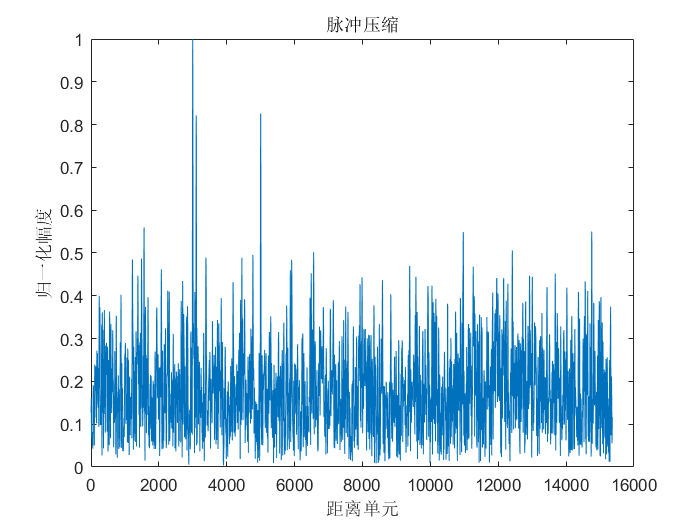

% signal=sr;
% tt=0:1/fs:Tr-1/fs;
%%=================脉冲压缩===================%% 
ttt=0:1/fs:Tp-1/fs;
ori=[exp(j*pi*u*ttt.^2).*exp(-j*2*pi*f0*ttt), zeros(1,length(tt)-length(ttt))];        %我不是很理解
signal_fft=fft(signal,[],2);
ori_fft=fft(ori);
shit=signal_fft.*conj(ori_fft);
pc=ifft(shit,[],2);
r_range=(0:length(t)-1)*totalR/(length(t)-1);
v_range = (-N/2:N/2-1)*c/2/f0/N/Tr;
plot(r_range,abs(pc(1,:))/max(max(abs(pc(1,:)))))

title('脉冲压缩')
xlabel('距离单元')
ylabel('归一化幅度')

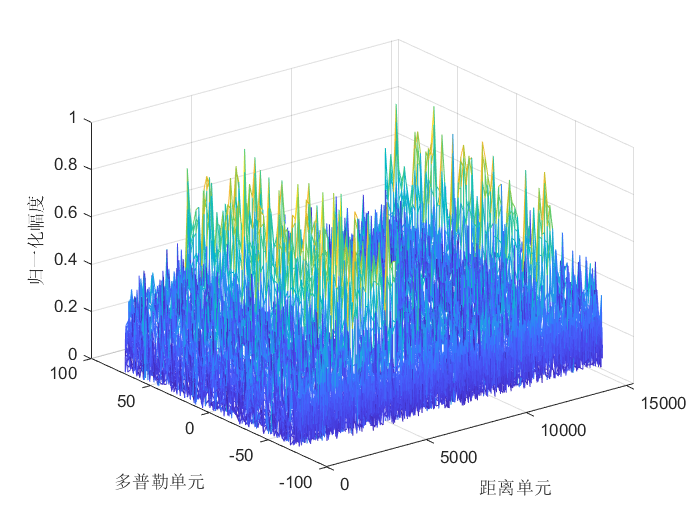


mesh(r_range,v_range,(abs(pc))/max(max((abs(pc)))))
xlabel('距离单元')
ylabel('多普勒单元')
zlabel('归一化幅度')

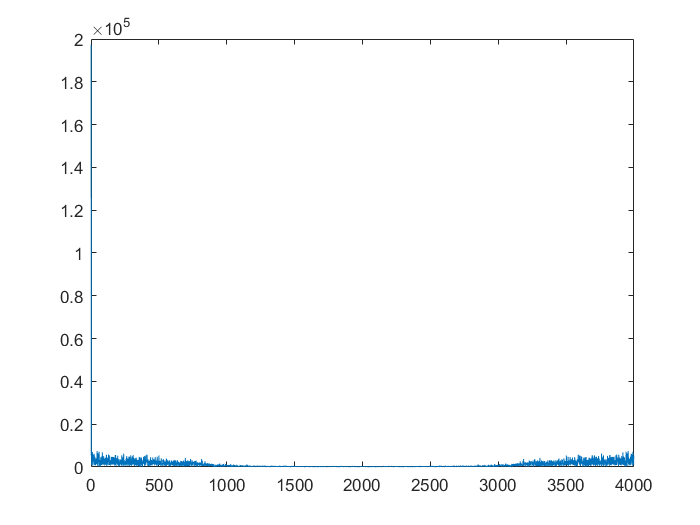

plot(1:4000, abs(fft(abs(pc(1,:)),4000)))       %fftshitf,1

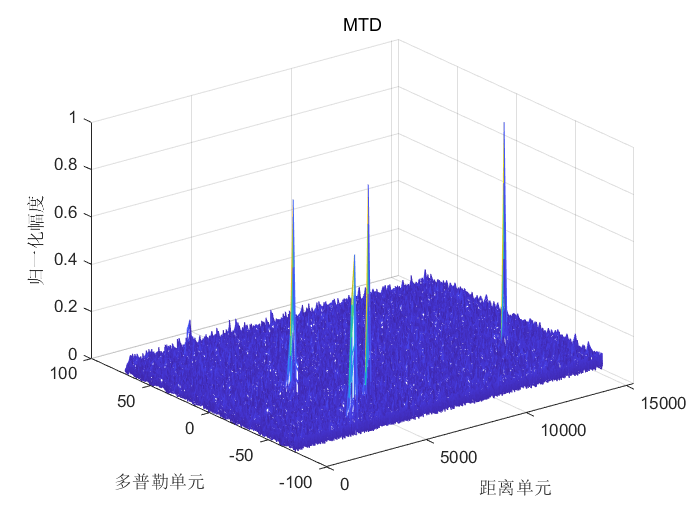


%%=================MTD===================%% 
% mtd=fft(pc);
% [m,n]=size(mtd);
% mtd=fftshift(mtd);
%mesh(1:n,1:m,abs(fftshift(mtd)))
r_range=(0:length(t)-1)*totalR/(length(t)-1);
% v_range = (-M_scale*N/2:M_scale*N/2-1)*c/2/f0/M_scale*N/Tr;

mtd=fft(pc);   %uuuu766通常K>M
 mtd=fftshift(mtd,1);
[m,n]=size(mtd);
mesh(r_range,v_range,abs(mtd)/max(max(abs(mtd))))
title('MTD')
xlabel('距离单元')
ylabel('多普勒单元')
zlabel('归一化幅度')


%%=================CA-CFAR===================%% 
pnum = 4;                                  %保护单元
rnum = 10;                                 %参考单元
pfa = 1e-6;                                %恒虚警率
Kk = pfa^(-1/(2*rnum))-1                %门限系数

Kk = 0.9953

cfar=zeros(N,SampleNumber);
mtd2=abs(mtd).^2;

for i=1:M_scale*N
    sss=mtd2(i,:);
    for ii=pnum+rnum+1:SampleNumber-pnum-rnum                   
        sIndex=[ii-pnum+rnum:ii-pnum-1 ii+pnum+1:ii+rnum+pnum];
        aaa(ii)=sum(sss(sIndex))/(2*rnum);
        %aaa=(pc2(i,j-5)+pc2(i,j-4)+pc2(i,j-3)+pc2(i,j-2)+pc2(i,j+2)+pc2(i,j+3)+pc2(i,j+4)+pc2(i,j+5))/8.0;
        thold(ii)=Kk*aaa(ii);
        if  (mtd2(i,ii)>thold(ii))%&&(mtd2(i,ii)>20)
            cfar(i,ii)=mtd2(i,ii);
        else
            cfar(i,ii)=0;
        end
    end
%     if(i==4)
%         plot(1:length(thold),10*log10(thold)/65)
%         hold on
%         plot(1:length(mtd(i,:)),10*log10(mtd2(i,:))/65)
%         hold off
%         legend({'门限','快时间'})
%         title('CA-CFAR')
%         xlabel('距离单元')
%         ylabel('归一化幅度')
%     end
end

位置 1 处的索引超出数组边界(不能超出 64)。

[m,n]=size(cfar);
mesh(r_range,v_range,(cfar)/max(max(cfar)));
title('CA-CFAR')
xlabel('距离单元')
ylabel('多普勒单元')

% 
% pnum = 4;                                  %保护单元
% rnum = 10;                                 %参考单元
% pfa = 1e-6;                                %恒虚警率
% K = (pfa^(-1/(2*rnum))-1);                %门限系数
% [target , L] = ca_cfar(mtd,K,pnum,rnum);
% [m,n] = size(target);
% dian = zeros(N,length(t));
% 
% 
% 
% for i = 1:n
%     dian(target(3,i),target(2,i)) = target(1,i);
% end
% figure
% %[x,y] = meshgrid(r_range,v_range);
% 
% [x,y] = size(dian);
% mesh(1:y,1:x,dian)
% xlabel('距离/m');ylabel('速度m/s')
% zlabel('幅度')
% title('CFAR检测出的目标点') 